# Train a DDPG Agent for the Warehouse Robot

## Define the environment

 Six continuous numeric state variables. Two continuous actions in the range [-1 1].

obsInfo = rlNumericSpec([6 1]);
actInfo = rlNumericSpec([2 1],"UpperLimit",1,"LowerLimit",-1);

env = rlSimulinkEnv("whrobot","whrobot/controller",obsInfo,actInfo);
env.ResetFcn = @randomstart;

## Define the agent

dt = 0.25;

opts = rlDDPGAgentOptions("SampleTime",dt,"ExperienceBufferLength",1e6,"MiniBatchSize",128);
agent = rlDDPGAgent(obsInfo,actInfo,opts);

learnopts = rlOptimizerOptions("LearnRate",5e-5,"GradientThreshold",10);
agent.AgentOptions.ActorOptimizerOptions = learnopts;
agent.AgentOptions.CriticOptimizerOptions = learnopts;

## Train the agent

Check to train agent from scratch.

dotraining = false;
maxsteps = round(30/dt);  % max episode time of 30s (simulation time)
clear plotRobot           % make sure visualization starts fresh   

Train agent or load pretrained agent from file. The pretrained agent `trainedNN` was trained for *NN*$\times 10^3$ episodes.

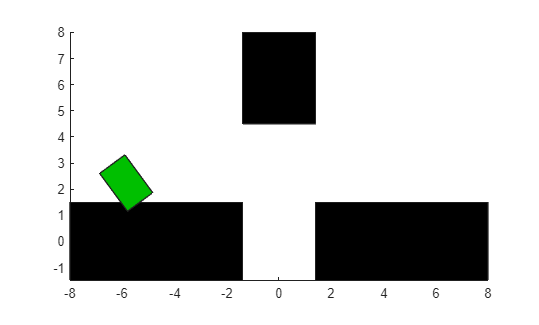

if dotraining
    opts = rlTrainingOptions( ...
        "MaxStepsPerEpisode",maxsteps, ... 
        "MaxEpisodes",15000, ...
        "ScoreAveragingWindowLength",50, ...
        "StopTrainingCriteria","AverageReward", ...
        "StopTrainingValue",2.5);
    info = train(agent,env,opts);
else
    load trainedDDPG
    agent = trained10;
end

## Evaluate the agent

Run multiple simulations.

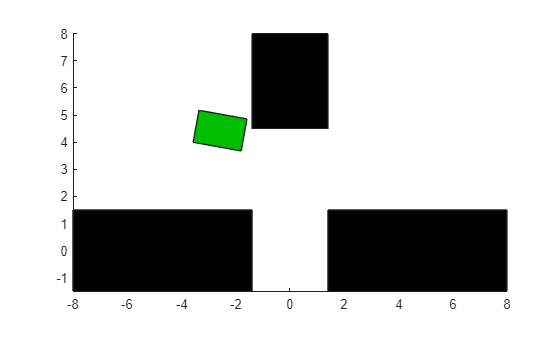

Error using rl.agent.AbstractAgent/sim (line 43)
Simulation aborted

numsim = 20;
simout = sim(agent,env,rlSimulationOptions("MaxSteps",maxsteps,"NumSimulations",numsim))

Episodes can end because (1) the robot succeeded, (2) the robot crashed into the shelves, (3) the episode reached the `MaxSteps` limit.

Determine which episodes were terminated (vs ran to `MaxSteps` limit). Then determine which of those were successful terminations (positive reward).

completed = arrayfun(@(x) any(x.IsDone.Data==1),simout);
succeeded = arrayfun(@(x) x.Reward.Data(x.IsDone.Data==1)>0,simout(completed));

Get the counts from each group.

Nsuccess = nnz(succeeded)
Ncrash = nnz(completed) - Nsuccess
Nnoresult = numsim - nnz(completed)
pie([Nsuccess;Ncrash;Nnoresult],[],["Succeeded","Crashed","Didn't reach goal"])

Get the time taken for successful runs.

T = arrayfun(@(x) x.IsDone.Time(end),simout(succeeded));
histogram(T)
mean(T)